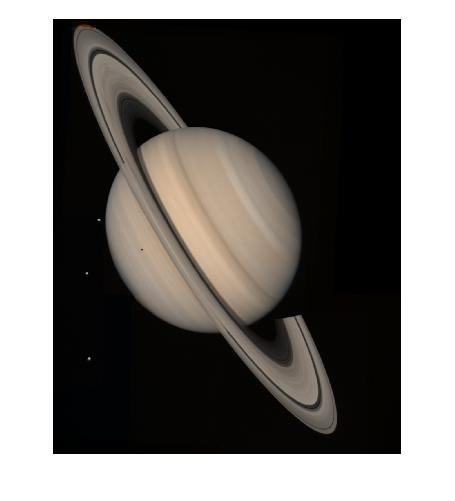

clear variables

% a)
saturn = imread('saturn.png');
figure, imshow(saturn);

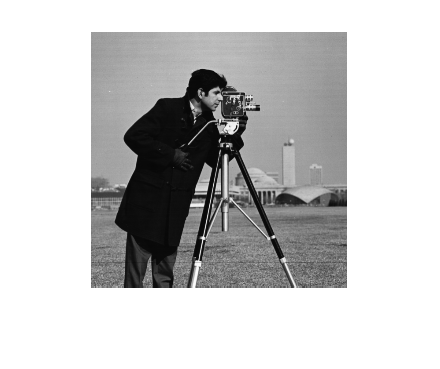

cameraman = imread('cameraman.tif');
figure, imshow(cameraman);

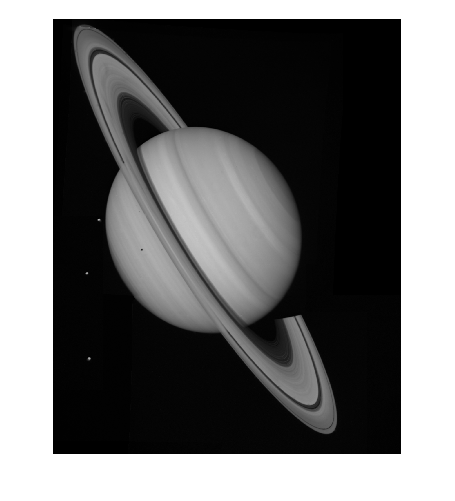

% b)
saturn = rgb2gray(saturn);
figure, imshow(saturn);

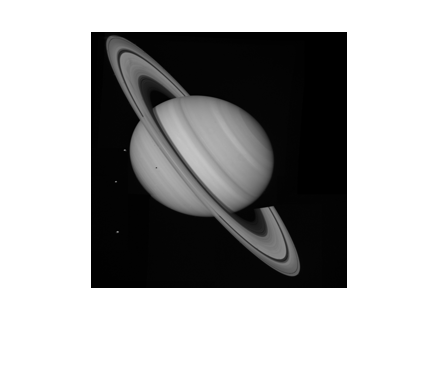

% c)
x = size(cameraman,1);
y = size(cameraman,2);
saturn = imresize(saturn,[x y]);
figure, imshow(saturn);

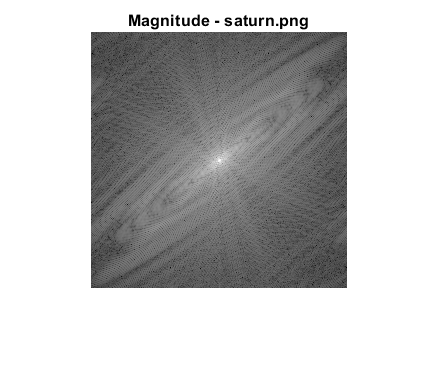

% d)
sat1 = fftshift(fft2(double(saturn)));
cam1 = fftshift(fft2(double(cameraman)));
% e)
mag_sat = log(abs(sat1));
pha_sat = angle(sat1);
figure, imshow(mag_sat,[]); title('Magnitude - saturn.png')

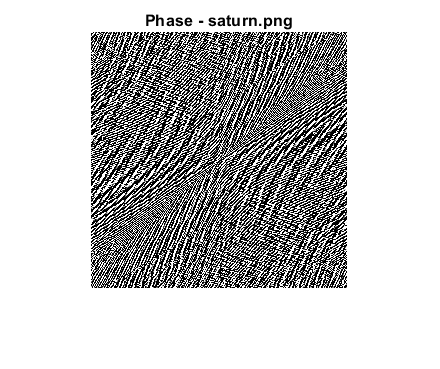

figure, imshow(pha_sat); title('Phase - saturn.png')

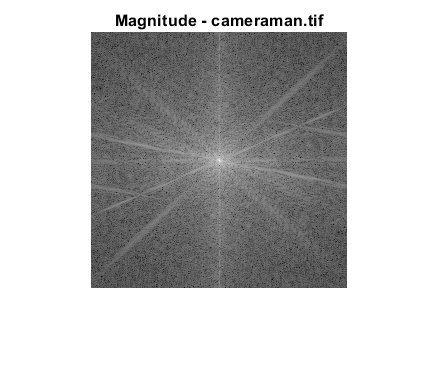

mag_cam = log(abs(cam1));
pha_cam = angle(cam1);
figure, imshow(mag_cam,[]); title('Magnitude - cameraman.tif')

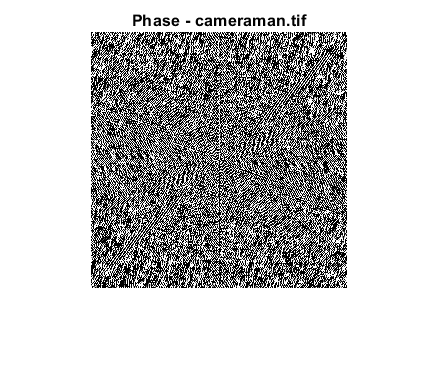

figure, imshow(pha_cam); title('Phase - cameraman.tif')